# Signal Detrending

- when you want to focus on local changes in the signal which is trending globally

## Linear Detrending

- generate a signal

- detrend it

- plot the signals

n = 2000; % number of signal points
signal = cumsum(randn(1,n)) + linspace(-30,30,n);
detrended = detrend(signal);
sig_mean = round(mean(signal), 2);
det_mean = round(mean(detrended), 2);

- Plot the signals

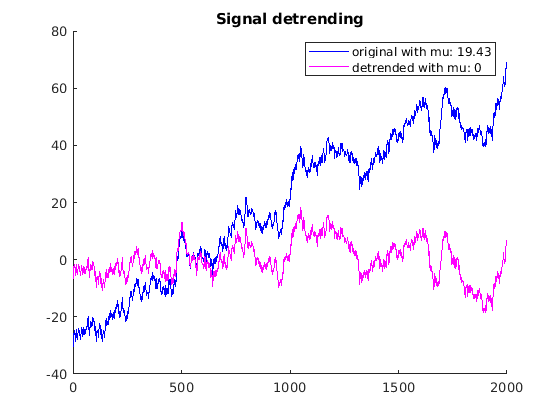

figure(1);
hold on;
sig_plot = plot(signal, 'b');
det_plot = plot(detrended, 'm');
legend([sig_plot, det_plot], ["original with mu: " + num2str(sig_mean), "detrended with mu: " + num2str(det_mean)]);
title("Signal detrending");
hold off;

## Polynomial detrending

- create the signal

n = 2000;
t = (1:n)';
k = 12; % number of poles for random amplitudes
poly = interp1(100*randn(k,1),linspace(1,k,n), 'pchip')';
signal2 = poly + 24*randn(n,1);

- plot the signal 

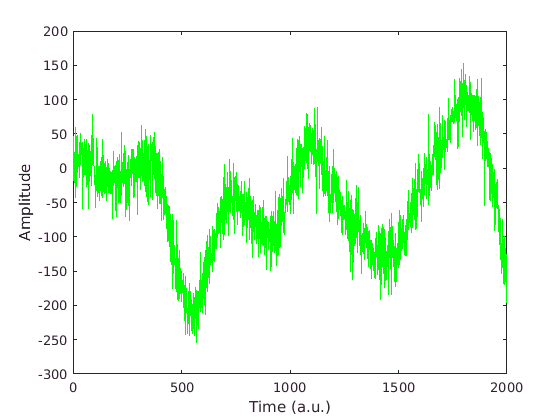

figure(2);
poly_sig = plot(t,signal2, 'g');
xlabel('Time (a.u.)'), ylabel('Amplitude');

- fit the signal to a polynomial curve

- use bayes information criterion to find the best polynomial order

- Similar to the elbow method when determining the number of clusters in a clustering task

warning('off', 'MATLAB:polyfit:RepeatedPointsOrRescale');
orders = (5:35)'; %polynomial orders to evaluate
sum_se = zeros(length(orders),1); %sum of square error

for i = 1:length(orders)
    y_hat = polyval(polyfit(t,signal2,orders(i)),t);
    sum_se(i) = sum((y_hat-signal2).^2)/n;
end

bayes_ic = n*log(sum_se) + orders*log(n);
[best,j] = min(bayes_ic);
display(j + min(orders) - 1);

    21



- Plot the bayes information criterion

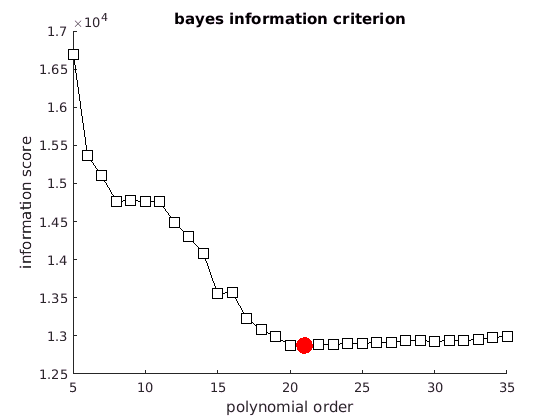

figure(3);clf;
hold on;
plot(orders, bayes_ic, 'ks-', 'markerfacecolor','w', 'markersize',10);
plot(orders(j), best, 'ro', 'markerfacecolor', 'r', 'markersize', 12);
title("bayes information criterion");
xlabel("polynomial order");
ylabel("information score");
hold off;

- fit a polynomial to the 21st order

p = polyfit(t,signal2,orders(j));
y_hat = polyval(p,t);
filtered = signal2 - y_hat;

- plot the filtered signal

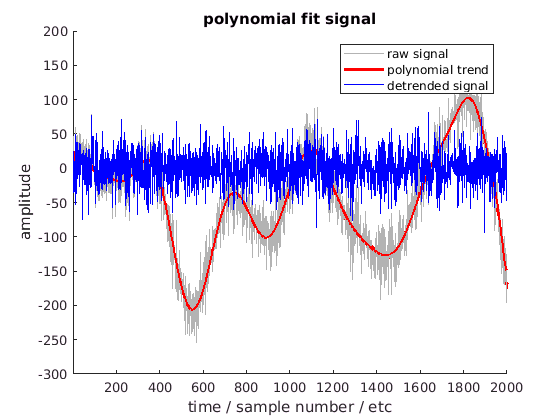

figure(4);
hold on;
orig_plot = plot(t,signal2);
set(orig_plot, 'color', [.7 .7 .7]); %make it grey
yhat_plot = plot(t,y_hat, 'r', 'linew', 2);
filt_plot = plot(t,filtered, 'b');
set(gca,'xlim',t([1 end]));
xlabel("time / sample number / etc");
ylabel("amplitude");
title("polynomial fit signal");
legend([orig_plot, yhat_plot, filt_plot], ["raw signal", "polynomial trend", "detrended signal"]);
hold off;